Aquí se aplica el método del gradiente ascendente para 3 dimensiones, pero se le añade ruido a la señal. En este caso se ha considerado que solo hay ruido en la medida y no en la posición de los robots. Se hacen 100 simulaciones de 3000 iteraciones cada una para calcular la media y la desviación estándar al ir variando variables como el radio de la formación o el step-size.

A continuación se determinan las condiciones iniciales:

clear
close all
hold off

%Desviación estándar es v=2
v=2;
%Desviación en la formación de robots es delta=0.1
delta=0.1;


N=6; %Número de robots (a partir de N=6 buena aproximación)
iteration=3000; %Número de iteraciones
step_size=0.1;
D=2.5; %Radio de la formación
S=10^-4*[100,1,1;1,10,0;1,0,10]; %Matriz
c0_initial=[20;20;20]; %Posición del centro inicial (initial guess)
r0=[0 0 0]'; %Centro de contaminación
w0=1; %Movimiento circular de un radián por segundo

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0_initial;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
simulation=100; %número de simulaciones
mod_rc=zeros(iteration,simulation);

Aquí se representa la media y la desviación estándar después de todas las simulaciones. Se ha considerado solo el ruido en la medida en este caso.

%Se aplica el método del gradiente
for k=1:100
    c0=c0_initial;
    for i=2:iteration
        grad_sum=0;
        for j=1:N
            %Determinación del ángulo azimutal
            phi=w0*t(i)+2*pi*j/N;
            %Determinación del ángulo polar
            if rem(j,2)==0
                theta=pi-0.955316618;
            else
                theta=0.955316618;
            end
            %Posición del robot individual (esfera)
            delta_i=0;
            %delta_i=normrnd(0,delta^2,[3 1]);
            
            r_i=c0+D*[sin(theta)*cos(phi);sin(theta)*sin(phi);cos(theta)]+delta_i;
            pos_rob(:,j,i)=r_i;
            %Suma para el gradiente (se tiene en cuenta cada
            %robot)
            v_i=normrnd(0,v^2);
            grad_sum=grad_sum+(100*exp(-r_i'*S*r_i)+v_i)*(r_i-c0);
        end
        %Aproximación del gradiente en el centro
        grad_centr=3/(N*D^2)*grad_sum;
        %Aplicación del método del gradiente ascendente
        c(:,i)=c0+step_size*grad_centr;
        c0=c(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
        mod_r_c(i)=norm(c0-r0); 
    end
    mod_rc(:,k)=mod_r_c;
end


Representación de la media y la desviación estándar:

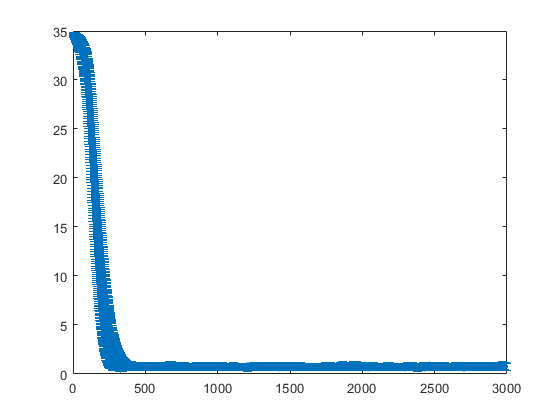

for h=1:iteration
    media(h)=mean(mod_rc(h,:));
    desv_std(h)=std(mod_rc(h,:));
end
errorbar(1:iteration,media,desv_std,'.')